# 数字图像处理 作业5 (4/1)

阮泉源 201930033629

## 图像傅里叶变换

    首先进行图像读取。

im_coser = imread('coser.jpg');

im_coser = rgb2gray(im_coser);

im_coser = im2double(im_coser);

[w, h] = size(im_coser);

    接下来有几个步骤：

- 生成$x+y$的矩阵

- 将原图像与${\left(-1\right)}^{x+y}$相乘，得到频移图像

- 分别从x方向与y方向对图像进行FFT变换，得到fft变换结果

- 通过对数变换压缩数据范围，显示fft图像

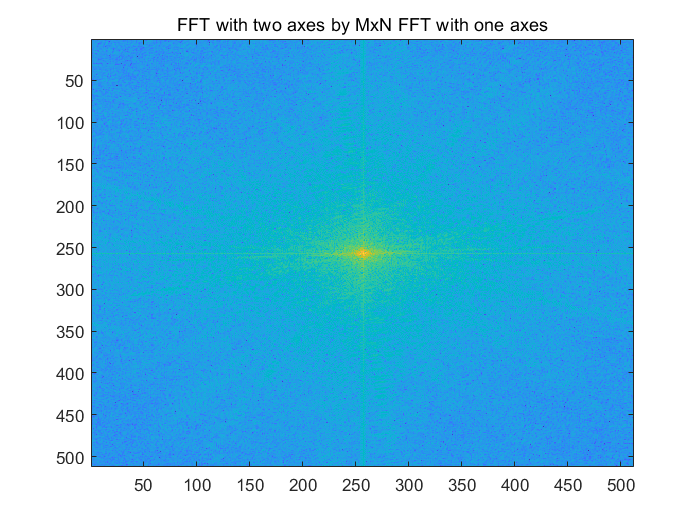

% generate x+y matrix
[x, y] = meshgrid(0:h-1, 0:w-1);

x_plus_y = x+y;

% multiply the original image and -1^(x+y)
im_scale = im_coser.*(-1).^(x_plus_y);

im_fft = zeros(w, h);

% MxN times FFT with one axis to tackle FFT with two axes
for i=1:h
    im_fft(:,i)=fft(im_scale(:,i));
end

for i=1:w
    im_fft(i,:)=fft(im_fft(i,:));
end

% zip the range of data
zip_im_fft = log(1+im_fft);

% display
figure;
imagesc(real(zip_im_fft))
title('FFT with two axes by MxN FFT with one axes')

    为了验证结果的正确性，使用MATLAB自带的函数进行二维FFT，结果如图所示，可以看到结果一致。

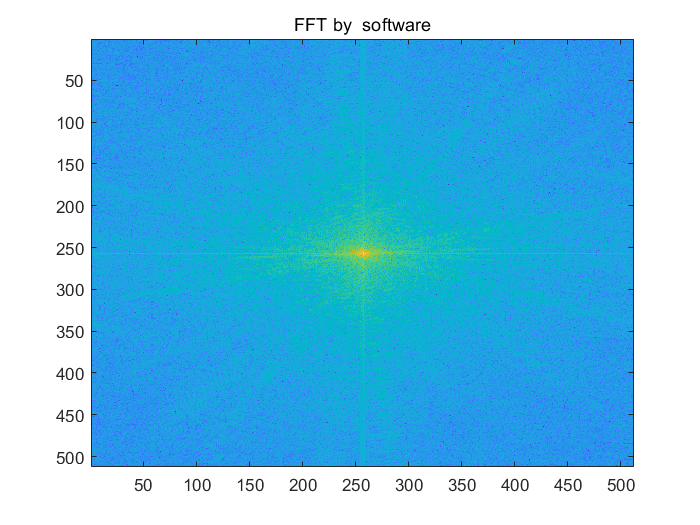

im_fft2 = fft2(im_coser);
im_fft2 = fftshift(im_fft2);

im_fft2_zip = log(1+im_fft2);

figure;
imagesc(real(im_fft2_zip));
title('FFT by  software')

    可以验证图像的傅里叶变换结果正确。